## Zadanie 

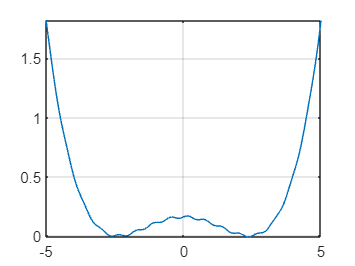

f = @(x) 0.01*sin(10*x)+(0.07*x.^2-0.4).^2;
fplot(f); grid on;

epsilon = 1.00e-04;
gamma = 0.001;

% 1)
x0 = [-8 -0.5];
[przedzial, i] = ekspansja(f, x0(1), x0(2), 2, 100);
iteracje_ekspansji = i

iteracje_ekspansji = 2

a = przedzial(1)

a = -4

b = przedzial(2)

b = -1

c = (a + b) / 2

c = -2.5000

[x_min, iteracje_interpolacji] = lagrange(f, a, b, c, epsilon, gamma, 100)

x_min = -2.6105

iteracje_interpolacji = 8

x_fminsearch = fminsearch(f, c)

x_fminsearch = -2.6105

[xp,xk,WYNIK,n,vector_a,vector_b]=golden_rat(f,przedzial,epsilon,100,2)

a = -4

b = -1

xp = -2.0989

xk = -2.0989

WYNIK = -2.0989

n = 23

vector_a =    -4.0000   -2.8541   -2.8541   -2.4164   -2.4164   -2.2492   -2.1459   -2.1459   -2.1459   -2.1215   -2.1064   -2.1064   -2.1064   -2.1029   -2.1007   -2.1007   -2.0998   -2.0993   -2.0993   -2.0991   -2.0990   -2.0990   -2.0989


vector_b =    -1.0000   -1.0000   -1.7082   -1.7082   -1.9787   -1.9787   -1.9787   -2.0426   -2.0820   -2.0820   -2.0820   -2.0914   -2.0971   -2.0971   -2.0971   -2.0985   -2.0985   -2.0985   -2.0988   -2.0988   -2.0988   -2.0989   -2.0989



% 2)
x0 = [1 8];
[przedzial, i] = ekspansja(f, x0(2), x0(1), 2, 100);
iteracje_ekspansji = i

iteracje_ekspansji = 1

a = przedzial(1)

a = 1

b = przedzial(2)

b = 4

c = (a + b) / 2

c = 2.5000

[x_min, iteracje_interpolacji] = lagrange(f, a, b, c, epsilon, gamma, 100)

x_min = 2.3624

iteracje_interpolacji = 6

x_fminsearch = fminsearch(f, c)

x_fminsearch = 2.3624

[xp,xk,WYNIK,n,vector_a,vector_b]=golden_rat(f,przedzial,epsilon,100,2)

a = 1

b = 4

xp = 2.3624

xk = 2.3624

WYNIK = 2.3624

n = 23

vector_a =     1.0000    1.0000    1.7082    2.1459    2.1459    2.1459    2.2492    2.3131    2.3131    2.3375    2.3525    2.3525    2.3583    2.3583    2.3605    2.3619    2.3619    2.3619    2.3622    2.3622    2.3623    2.3623    2.3624


vector_b =     4.0000    2.8541    2.8541    2.8541    2.5836    2.4164    2.4164    2.4164    2.3769    2.3769    2.3769    2.3676    2.3676    2.3641    2.3641    2.3641    2.3632    2.3627    2.3627    2.3625    2.3625    2.3624    2.3624


## Zadania problemowe

### Zadanie 1

f = @(x) 2.5 * (x(1)^2 - x(2))^2 + (1 - x(1))^2;
x0 = [0.25, 0.5];       % punkt początkowy
x1_end = [-0.1, -0.1];  % punkt końcowy

direction = x1_end - x0; % Kierunek wektora
direction = direction / norm(direction);  % normalizacja wektora

% Znajdowanie minimum funkcji w kierunku wektora
[x_min, f_min] = fminsearch(@(x) f(x0 + x * direction), 0);
x_min = x0 + x_min * direction;
disp('Wartość minimalna funkcji:');

Wartość minimalna funkcji:


disp(f_min);

    0.9455



disp('Współrzędne punktu minimalnego:');

Współrzędne punktu minimalnego:


disp(x_min);

    0.1033    0.2486



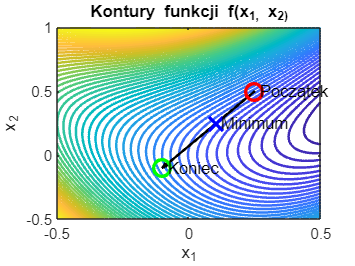

f = @(x1, x2) 2.5 * (x1.^2 - x2).^2 + (1 - x1).^2;

x1 = linspace(-0.5, 0.5, 100);
x2 = linspace(-0.5, 1, 100);
[X1, X2] = meshgrid(x1, x2);
Z = f(X1, X2);

% kontury funkcji
figure;
contour(X1, X2, Z, 50, 'LineWidth', 1.5);
xlabel('x_1');
ylabel('x_2');
title('Kontury funkcji f(x_1, x_2)');

hold on;
% wektor kierunku
quiver(x0(1), x0(2), direction(1), direction(2), sqrt((x0(1)-x1_end(1))^2 + (x0(2)-x1_end(2))^2), 'k', 'LineWidth', 1.5);
% punkt startowy
plot(0.25, 0.5, 'ro', 'MarkerSize', 10, 'LineWidth', 2);
text(0.25, 0.5, ' Początek');

% punkt końcowy
plot(-0.1, -0.1, 'go', 'MarkerSize', 10, 'LineWidth', 2);
text(-0.1, -0.1, ' Koniec');

% znalezione minimum
plot(x_min(1), x_min(2), 'bx', 'MarkerSize', 12, 'LineWidth', 2);
text(x_min(1), x_min(2), ' Minimum');
hold off;

### Zadanie 2

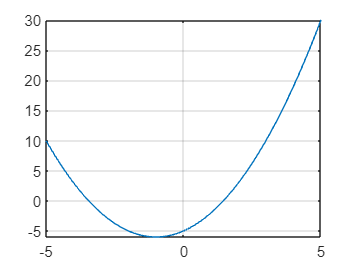

f = @(x) x.^2 + 2*x - 5;
figure
fplot(f); grid on;

x_zeros = zeros(2, 1);
x_zeros(1) = fminsearch(@(x) abs(f(x)), -5);
x_zeros(2) = fminsearch(@(x) abs(f(x)), 0);

x_value = zeros(2, 1);
x_value(1) = fminsearch(@(x) abs(f(x) - 1), -5);
x_value(2) = fminsearch(@(x) abs(f(x) - 1), 0);

disp('Punkty zerowe funkcji:');

Punkty zerowe funkcji:


disp(x_zeros);

   -3.4495
    1.4495



disp('Punkty dla których funkcja przyjmuje wartość 1:');

Punkty dla których funkcja przyjmuje wartość 1:


disp(x_value);

   -3.6458
    1.6458



### Zadanie 3

G1 = tf([0, 1], [1, 2 ,2.25, 1.25]);
[G1p_Licz, G1p_Mian] = pade(0.5, 3);
G1p = tf(G1p_Licz, G1p_Mian);
G1 = G1 * G1p;
% Odpowiedź skokowa transmitancji G1
t = 0:0.1:30;  % Czas symulacji
u = ones(size(t));  % Skok jednostkowy jako wejście
y1 = lsim(G1, u, t);

delay_G1 = 0.5;
% Wartość końcowa odpowiedzi skokowej G1 (twierdzenie o wartości końcowej)
G1_final_value = y1(end);

% Definicja funkcji celu
objectiveFunction = @(x) norm(lsim(tf([0 G1_final_value], [1 x],'InputDelay', delay_G1), u, t) - G1_final_value);

% Początkowe wartości parametrów transmitancji G2
initialGuess = [1];  

% Minimalizacja funkcji celu przy użyciu fminsearch
optimalParameters = fminsearch(objectiveFunction, initialGuess);

% Transmitancja optymalnego systemu dynamicznego G2
G2 = tf([0 G1_final_value], [1 optimalParameters],'InputDelay', delay_G1)

G2 =
 
                   0.8
  exp(-0.5*s) * ----------
                s + 0.9908
 
Continuous-time transfer function.
Model Properties


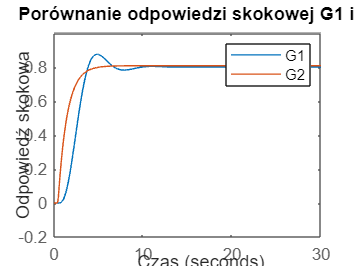


% Porównanie odpowiedzi skokowej G1 i G2
figure;
lsim(G1, u, t);
hold on
lsim(G2, u, t);
legend('G1', 'G2');
xlabel('Czas');
ylabel('Odpowiedź skokowa');
title('Porównanie odpowiedzi skokowej G1 i G2');

function [przedzial, i] = ekspansja(fun, x0, x1, a, n_max)
    if fun(x0) == fun(x1)
        przedzial = [x0, x1];   
        return
    elseif fun(x0) < fun(x1)
        x1 = -x1;
        if fun(x0) <= fun(x1)
            przedzial = [x1, -x1];  
            return
        end
    end
    
    i = 0;
    x_minus = x0;
    x_i = x1;
    x_plus = x1*a;
    while fun(x_i) > fun(x_plus) 
        if i > n_max
            error("Przekroczono ilość iteracji!") 
        else
            i = i + 1;
            x_minus = x_i;
            x_i = x_plus;
            x_plus = x_plus * a;
        end
    end
    
    if x_minus < x_plus
        przedzial = [x_minus, x_plus];  
        return
    else
        przedzial = [x_plus, x_minus];  
        return
    end
end

function [x, i] = lagrange(fun, a, b, c, epsilon, gamma, Nmax)
i = 1;
a(1) = a;
b(1) = b;
c(1) = c;

while(1)
    fa = fun(a(i));
    fb = fun(b(i));
    fc = fun(c(i));
    
    licz = fa*(c(i)^2-b(i)^2) + fc*(b(i)^2-a(i)^2) + fb*(a(i)^2-c(i)^2);
    mian = fa*(c(i)-b(i)) + fc*(b(i)-a(i)) + fb*(a(i)-c(i));

    d(i) = 0.5 * licz / mian;
    fd = fun(d(i));
    
    if(a(i) < d(i) && d(i) < c(i))
        if(fd < fc)
           a(i + 1) = a(i);
           c(i + 1) = d(i);
           b(i + 1) = c(i);
        else
            a(i + 1) = d(i);
            c(i + 1) = c(i);
            b(i + 1) = b(i);
        end
    else
        if(c(i) < d(i) && d(i) < b(i))
           if(fun(d(i)) < fun(c(i)))
              a(i + 1) = c(i);
              c(i + 1) = d(i);
              b(i + 1) = b(i);
           else
               a(i + 1) = a(i);
               c(i + 1) = c(i);
               b(i + 1) = d(i);
           end
        else
            error('Algorytm nie jest zbieżny')
        end
    end
    
    i = i + 1;
    if(i > Nmax)
        error('Nie osiągnięto dokładności epsilon w zadanych iteracjach')
    end

    fa = fun(a(i));
    fb = fun(b(i));
    fc = fun(c(i));
    
    licz = fa*(c(i)^2-b(i)^2) + fc*(b(i)^2-a(i)^2) + fb*(a(i)^2-c(i)^2);
    mian = fa*(c(i)-b(i)) + fc*(b(i)-a(i)) + fb*(a(i)-c(i));

    d(i) = 0.5 * licz / mian;
    
    if((b(i) - a(i) < epsilon) || (abs(d(i) - d(i-1)) <= gamma))
        x = d(i);
        return;
    end
end
end

function [xp,xk,WYNIK,n,vector_a,vector_b]=golden_rat(fx,przedzial,epsilon,N_max,alfa)
    i = 1;
    alfa = 0.6180339;
    a(1)=przedzial(1)
    b(1)=przedzial(2)
    c(1) = b(1) - alfa * (b(1) - a(1));
    d(1) = a(1) + alfa * (b(1) - a(1));
    while abs(b(i)-a(i))>epsilon
        if fx(c(i)) < fx(d(i))
            a(i + 1) = a(i);
            b(i + 1) = d(i);
            c(i + 1) = b(i + 1) - alfa*(b(i + 1) - a(i + 1));
            d(i + 1) = c(i);
        else
            a(i + 1) = c(i);
            b(i + 1) = b(i);
            c(i + 1) = d(i);
            d(i + 1) = a(i+1) + alfa*(b(i + 1) - a(i + 1));
        end
        i = i + 1;
        if i > N_max
            disp("ERROR");
        end
    end
    vector_a=a; vector_b=b;
    xp=a(i);
    xk=b(i);
    WYNIK=0.5*(a(i)+b(i));
    n=i;
    return
end

W zadaniach problemowych skorzystac z z twierdzenia o wartości końcowej!